### Exercise 14.3 from sim14_integral.m

Papula 3.1.2 page 255

## 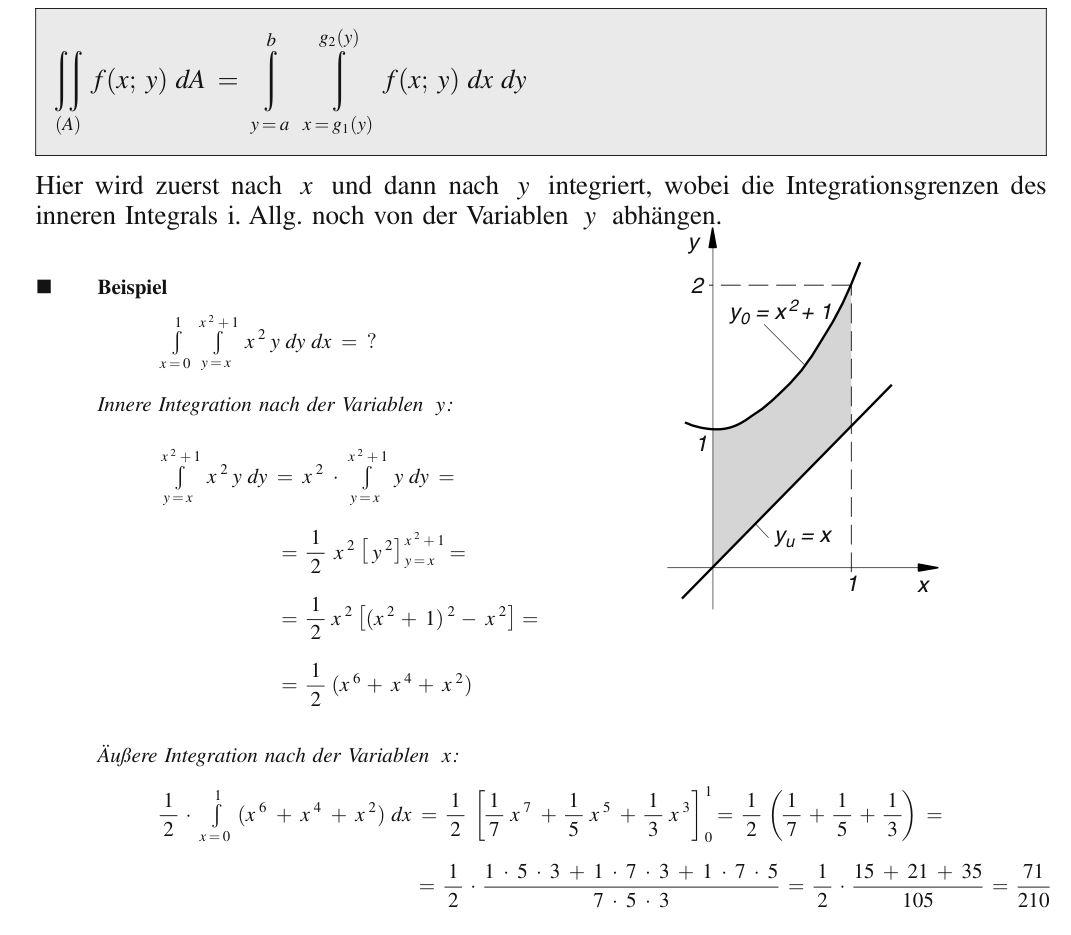

## Surface integral in polar coordinates

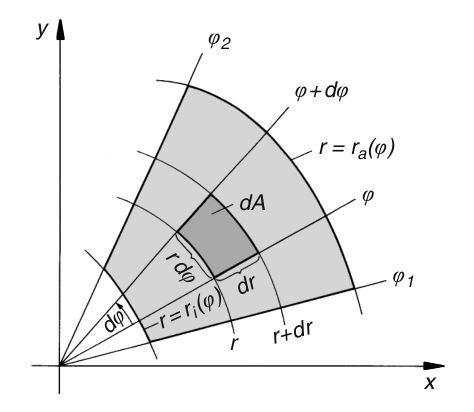

switch coordinates: $x,y\;\to r,\varphi$ 


$$\begin{array}{l}
x=r\;\cos \left(\varphi \right)\\
y=r\;\sin \left(\varphi \right)
\end{array}$$


adapt area element: $\textrm{dx}\;\textrm{dy}\;\to r\;d\varphi \;\textrm{dr}$ 

adapt integral limits


$$\int_x  \int_y f(x,y) ~dx ~dy \rightarrow \int_r \int_\varphi f(r,\varphi) ~r~dr ~d\varphi$$


#### example: moment of inertia of a circular disc


$$J = \int \!\!\!\!\! \int_{circle} \rho ~ x^2 ~dx~dy$$


x is distance from axis of rotation

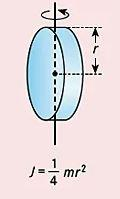

clear,clc
m=1;            % mass
R=1;            % disc radius      
rho=m/pi/R^2;   % mass density per area
fc=@(x,y) rho*x.^2;

% change to integral in polar coordinates
fp = @(phi,r) fc(r.*cos(phi),r.*sin(phi)).*r;
% integrate considering limits in r and phi
J = integral2(fp,0,2*pi,0,R) 

J = 0.2500

If the integrand depends on radius r only (and not on $\varphi$)

the surface integral in polar coordinates can be expressed with an 

single integral over r  and the factor of $2\pi r$ in the integrand

#### example: moment of inertia of a circular disc


$$J =  \int \!\!\!\!\! \int_{circle} \rho~ r^2 ~dx~dy$$


r is distance from axis of rotation

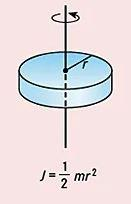

m=1;            % mass
R=1;            % disc radius      
rho=m/pi/R^2;   % mass density per area

J = integral(@(r) rho*r.^2* 2*pi.*r,0,R )

J = 0.5000

#### Exercise 14.4: Calculate the area of a circle with radius R by integrating the constant function f(r)=1 in polar coordinates

R=1;




## Volume integral in spherical coordinates

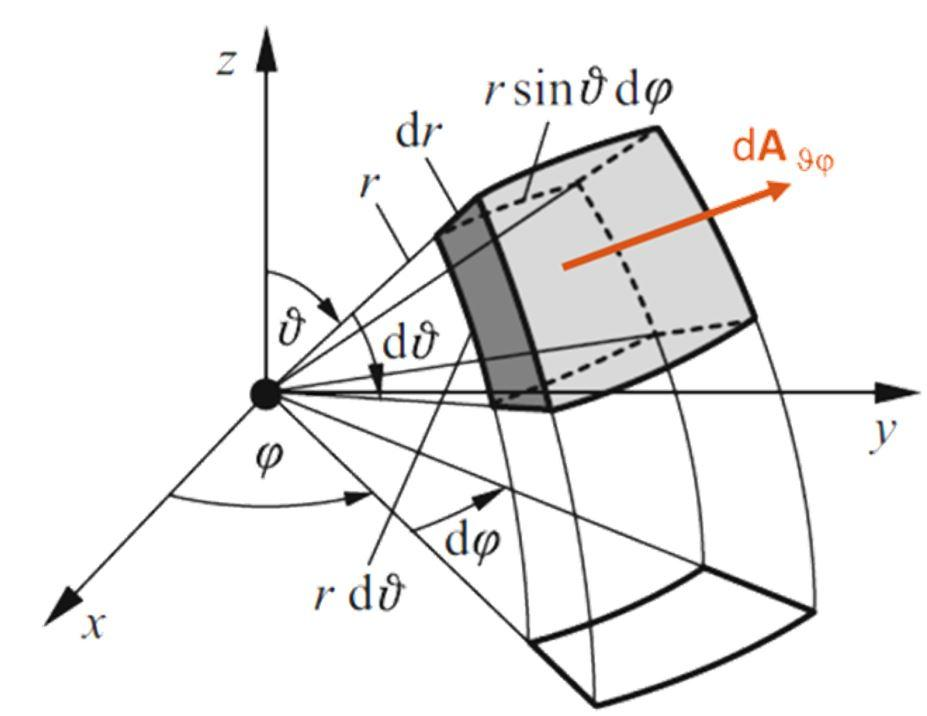

switch coordinates: $x,y,z\;\to r,\vartheta ,\varphi$ 


$$\begin{array}{l}
x=r\;\sin \;\vartheta \;\;\cos \;\varphi \\
y=r\;\sin \;\vartheta \;\;\sin \;\varphi \\
z=r\;\cos \;\vartheta 
\end{array}$$


adapt area element: $\textrm{dx}\;\textrm{dy}\;\textrm{dz}\;\to {\mathrm{r}}^2 \;\sin \;\vartheta \;\textrm{dr}\;d\vartheta \;d\varphi \;$ 

adapt integral limits


$$\int_x  \int_y \int_z f(x,y,z) ~dx ~dy ~dz \rightarrow \int_r \int_\vartheta \int_\varphi f(r,\vartheta ,\varphi) ~ r^2 \sin \vartheta ~dr ~d\vartheta ~d\varphi$$


#### example: moment of inertia of a sphere


$$J =  \int \!\!\!\!\! \int \!\!\!\!\! \int_{sphere} \rho ~ d^2 ~dx~dy~dz$$


$d=\sqrt{x^2 +y^2 }$ is distance from axis of rotation

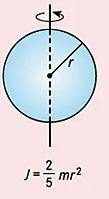

m=1;            % mass
R=1;            % disc radius 
V=4*pi/3*R^3;   % sphere volume
rho=m/V;        % mass density 

fc=@(x,y,z) rho*(x.^2+y.^2);

% change to integral in spherical coordinates
fs=@(theta,phi,r) fc(r.*sin(theta).*cos(phi), ...
                     r.*sin(theta).*sin(phi), ...
                     r.*cos(theta)).*r.^2.*sin(theta);
% integration limits theta[0,pi], phi[0,2pi] und r[0,R]
integral3(fs,0,pi,0,2*pi,0,R) 

ans = 0.4000

If the integrand depends on radius r only (and not on $\vartheta \;\textrm{or}\;\varphi$)

the volume integral in spherical coordinates can be expressed with a 

single integral over r  and the factor of $4\pi r^2$ in the integrand

#### Exercise 14.5: Calculate the volume of a sphere with radius R by integrating the constant function f(r)=1 in spherical coordinates

R=1;





#### Exercise 14.6: [Skineffect](https://en.wikipedia.org/wiki/Skin_effect) in a wire with circular cross section

**skin effect** is the tendency of an alternating electric current (AC) to become distributed within a conductor such that the current density is largest near the surface of the conductor and decreases exponentially with greater depths in the conductor

current density: $j(r) = J_s \cdot e^{\frac{-(R-r)}{\delta}}$

plot j(r) and calculate the total current in the conductor for the given parameters.

R = 1e-3;           % radius of conductor [m]
mu = 4e-7*pi;       % vacuum permeability [Vs/m^2]
sig = 56e6;         % conductivity Cu [S/m^2] 
f = 1000e3;         % frquency [Hz]
Js = 2.54e6;        % curent density at conductor surface [A/m^2)

delta=sqrt(2/sig/2/pi/f/mu);    % skin depth



